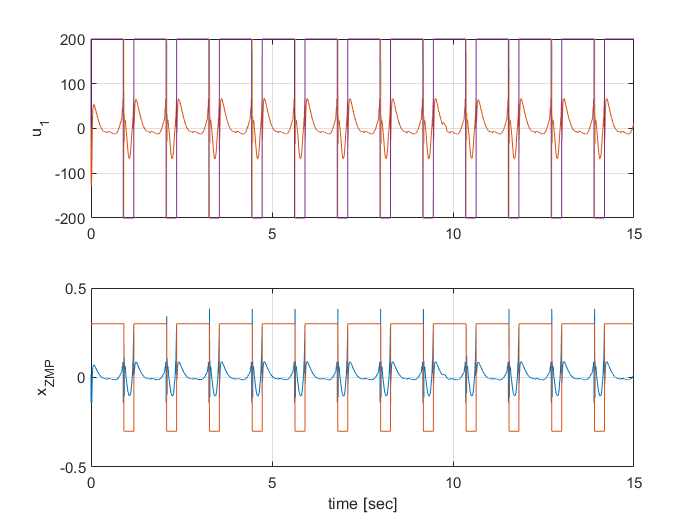

% des_traj = [
%     ddx_CoM_des; ddy_CoM_des; ddx_sw_des; ddy_sw_des;
%     dx_CoM_des;  dy_CoM_des;  dx_sw_des;  dy_sw_des;
%     x_CoM_des;   y_CoM_des;   x_sw_des;   y_sw_des];

% x_start = 11.5;
% x_end = 12.8;

% x_start = 10.35;
% x_end = 10.654;

x_start = 0;
x_end = time(end);

figure()
subplot(2,1,1)
plot(time, inputTorque(:,1))
hold on
plot(time, U_test(:,1))
plot(time, 200*flag(:,1))
grid on
xlim([x_start,x_end])
ylabel('u_1')

plot(time, 200*flag_des)
% plot(time, U_test(:,2))

% subplot(3,1,2)
% % plot(time, des_traj(:,2))
% % ylabel('ddy_{CoM}^*')
% % grid on
% % xlim([x_start,x_end])
% % hold on
% % plot(time, 0.5*flag(:,1))
% 
% plot(time, des_traj(:,10))
% ylabel('y_{CoM}^*')
% grid on
% xlim([x_start,x_end])
% hold on
% plot(time, CoM_acc(:,2))
% plot(time, 0.05*flag(:,1)+1)

subplot(2,1,2)
plot(time, x_ZMP_noImpact)
% plot(time, U_test(:,3))
grid on
hold on
plot(time, 0.3*flag(:,1))
xlim([x_start,x_end])
ylabel('x_{ZMP}')
ylim([-0.5,0.5])
xlabel('time [sec]')


% plot(time, U_test(:,3))

% legend('x_{ZMP, new}', 'f_{SS}', 'x_{ZMP, simulink}')


## ZMP

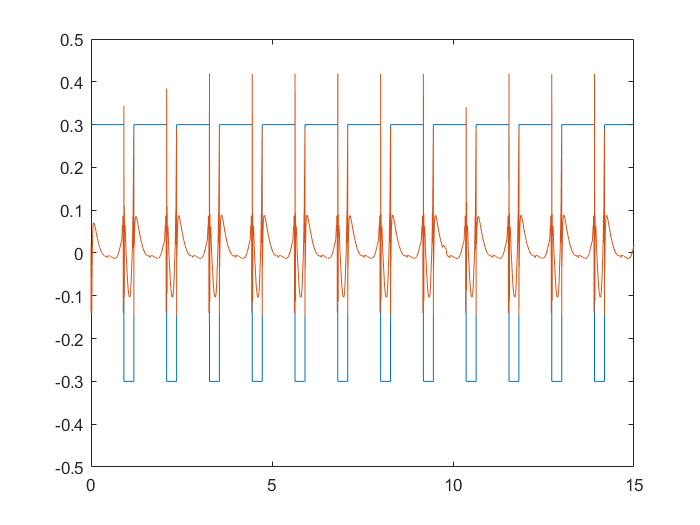

ZMP_dummy = (inputTorque(:,1) + x_foot_CoM*m_foot*params.g) ./ (GRF_simulink(:,2) + m_foot*params.g);

figure()
plot(time, 0.3*flag(:,1))
hold on
plot(time, ZMP_dummy)
ylim([-0.5,0.5])
xlim([x_start,x_end])

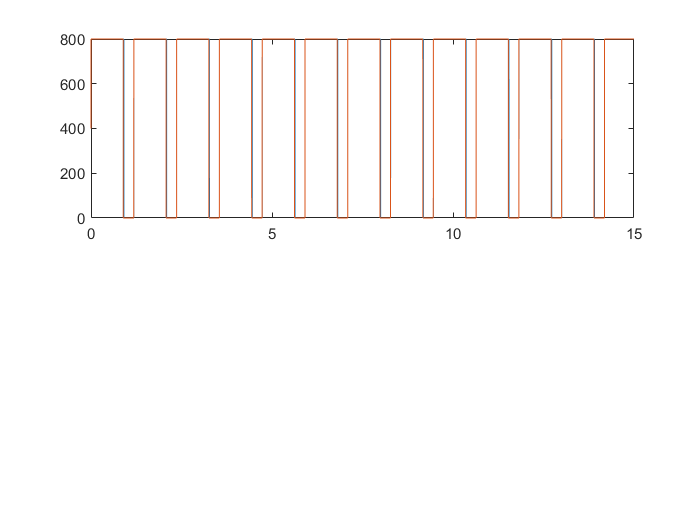

figure
subplot(2,1,1)
plot(time, 400*(flag(:,1) + 1))
hold on
plot(time, 400*(flag_des + 1))

plot(time, lambda_GRF_y)

Unrecognized function or variable 'lambda_GRF_y'.

xlim([x_start,x_end])
ylabel('stance F_{y, GRF}')

subplot(2,1,2)
plot(time, 400*(flag(:,1) + 1))
hold on
plot(time, 400*(flag_des + 1))
plot(time, GRF(:,4))

plot(time, force(:,2))
xlim([x_start,x_end])
ylabel('swing F_{y, GRF}')


## GRF

figure()

plot(time, GRF(:,2))
hold on
plot(time, GRF_simulink(:,2))

figure()
plot(time, GRF_simulink(:,2) - GRF(:,2))

figure()
subplot(3,1,1)
plot(time, inputTorque(:,1))
hold on
plot(time, U_test(:,1))
plot(time, 200*flag(:,1))
grid on
xlim([x_start,x_end])
ylabel('u_1')

subplot(3,1,2)
plot(time, des_traj(:,2))
ylabel('ddy_{CoM}^*')
grid on
xlim([x_start,x_end])
hold on
plot(time, 0.5*flag(:,1))

subplot(3,1,3)
plot(time, medfiltX_ZMP)
grid on
hold on
plot(time, 0.3*flag(:,1))
xlim([x_start,x_end])
ylabel('x_{ZMP} (median filter)')

figure()
plot(time, U_test(:,2))
hold on
plot(time, x_ZMP)
xlim([x_start,x_end])